2-1

f_s = 450; f_p = 1e3; A_sdB = 30; A_pdB = 3; F_s = 4e3;

omega_p = (2*pi*f_p)/F_s; omega_s = (2*pi*f_s)/F_s;

Omega_p = 2*F_s*tan(omega_p/2)

Omega_p = 8.0000e+03

Omega_s = 2*F_s*tan(omega_s/2)

Omega_s = 2.9514e+03

nu = Omega_p/Omega_s;

n_value(A_sdB, A_pdB, nu)

e = 1.000000
n = 4.000000

Dvs. filterordenen n = 4.

b_p = 1; a_p = [1 2.6131 3.4142 2.6131 1];

H_proto = tf(b_p, a_p)


H_proto =
 
                      1
  -----------------------------------------
  s^4 + 2.613 s^3 + 3.414 s^2 + 2.613 s + 1
 
Continuous-time transfer function.


2-2

for højpas skal $s\longrightarrow \frac{\Omega_p }{s}$

[bt, at] = lp2hp(b_p, a_p, Omega_p);
H_hp = tf(bt, at)


H_hp =
 
      s^4 - 8.32e-12 s^3 - 5.07e-08 s^2 - 0.0003369 s
  --------------------------------------------------------
  s^4 + 2.09e04 s^3 + 2.185e08 s^2 + 1.338e12 s + 4.096e15
 
Continuous-time transfer function.


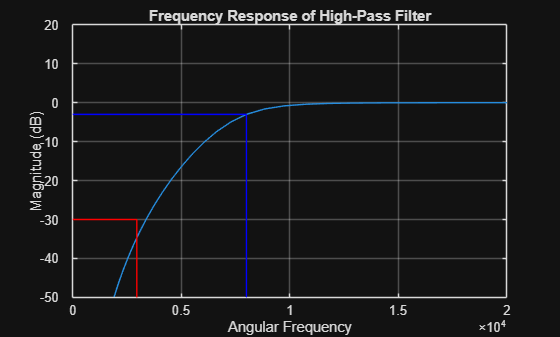

[h, w] = freqs(bt, at);

figure;
plot(w, 20*log10(abs(h)));
ylim([-50 20]);
xlim([0 20e3]);
    line([Omega_s Omega_s],[-A_sdB -50], 'Color','r');
    line([Omega_p Omega_p], [-A_pdB -50], 'Color', 'b');
    line([0 Omega_s], [-A_sdB -A_sdB], 'Color', 'r');
    line([0 Omega_p], [-A_pdB -A_pdB], 'Color', 'b');
title('Frequency Response of High-Pass Filter');
xlabel('Angular Frequency');
ylabel('Magnitude (dB)');
grid on;

Ved grafen ses der at ved vinkel frekvenserne $\Omega_p$ og $\Omega_s$ er der passene dæmpning iflg kravene.

2-3

For at transformere det anolge til det digitale skal $z=\frac{1+\frac{{\textrm{sT}}_s }{2}}{1-\frac{{\textrm{sT}}_s }{2}}$

[bd, ad] = bilinear(bt, at, F_s);


H_d = tf(bd, ad,1/F_s, 'Variable', 'z^-1')


H_d =
 
  0.09398 - 0.3759 z^-1 + 0.5639 z^-2 - 0.3759 z^-3 + 0.09398 z^-4
  ----------------------------------------------------------------
  1 - 4.545e-16 z^-1 + 0.486 z^-2 + 1.585e-16 z^-3 + 0.01767 z^-4
 
Sample time: 0.00025 seconds
Discrete-time transfer function.


2-4

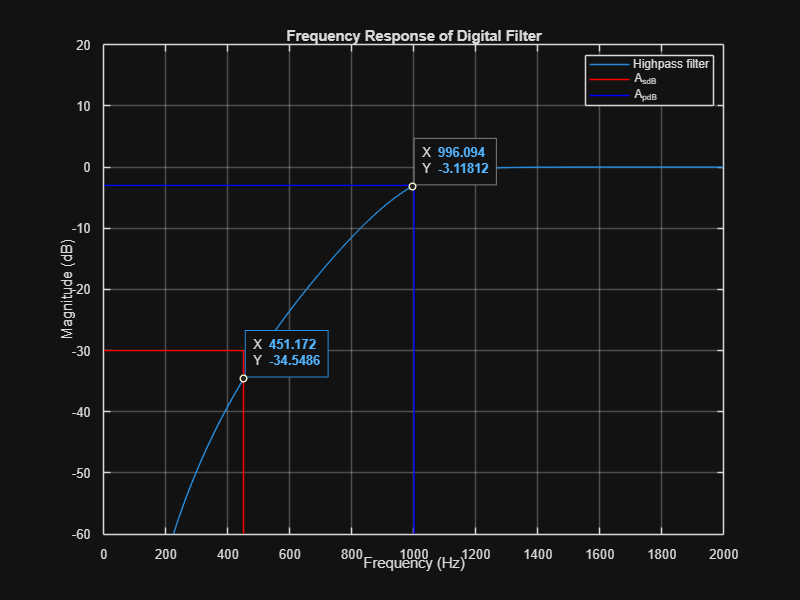

[hd, f] = freqz(bd, ad, 1024, F_s);

figure(Position = [100 200 800 600]);
plot(f, 20*log10(abs(hd)));
ylim([-60 20]);
xlim([0 2000]);
    line([f_s f_s],[-A_sdB -60], 'Color','r');
    line([f_p f_p], [-A_pdB -60], 'Color', 'b');
    line([0 f_s], [-A_sdB -A_sdB], 'Color', 'r');
    line([0 f_p], [-A_pdB -A_pdB], 'Color', 'b');
title('Frequency Response of Digital Filter');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
legend('Highpass filter', 'A_{sdB}', 'A_{pdB}');
grid on;
 
HigpassFilterLine2 = findobj(gcf, "DisplayName", "Highpass filter");
datatip(HigpassFilterLine2,996.1,-3.118);
datatip(HigpassFilterLine2,451.2,-34.55);

4-1

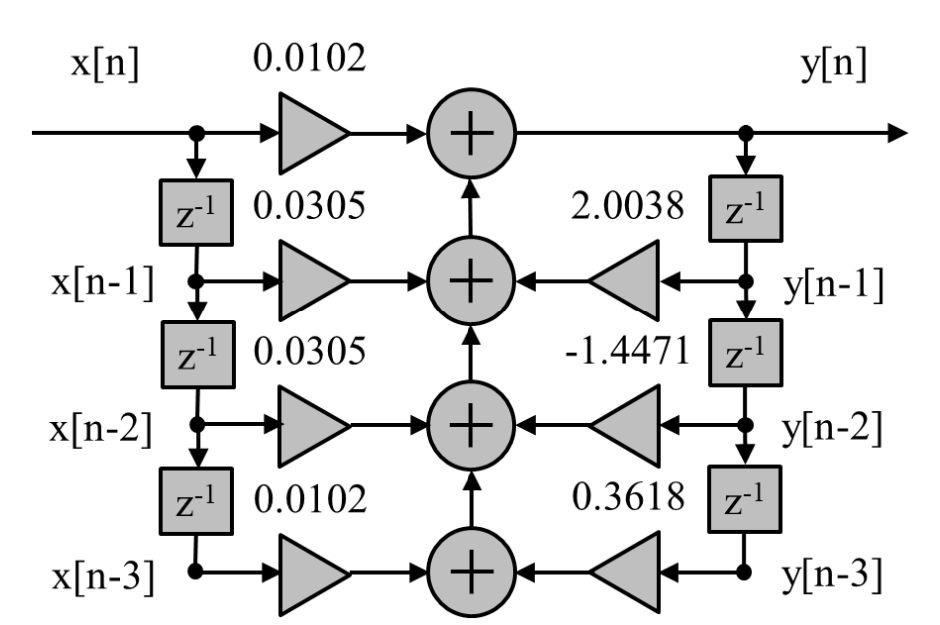

clear; clc;
F_s = 5e3; b = [0.0102 0.0305 0.0305 0.0102]; a = [1 -2.0038 1.4471 -0.3618];


Det er et IIR filter, fordi der findes a koefficienter.


tf(b, a, 1/F_s, 'Variable', 'z^-1')


ans =
 
  0.0102 + 0.0305 z^-1 + 0.0305 z^-2 + 0.0102 z^-3
  ------------------------------------------------
     1 - 2.004 z^-1 + 1.447 z^-2 - 0.3618 z^-3
 
Sample time: 0.0002 seconds
Discrete-time transfer function.


4-2

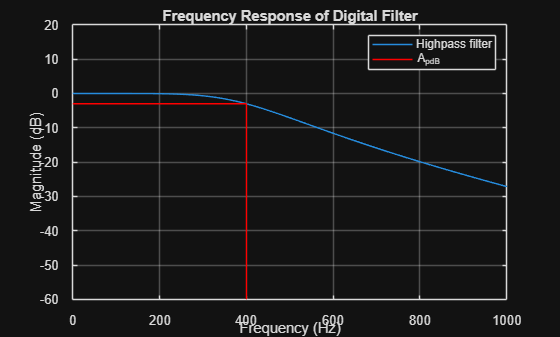

[h, f] = freqz(b, a, 1024, F_s);
f_p = 400; A_pdB = 3;

figure;
plot(f, 20*log10(abs(h)));
ylim([-60 20]);
xlim([0 1e3]);
grid on;
    line([f_p f_p], [-A_pdB -60], 'Color', 'r');
    line([0 f_p], [-A_pdB -A_pdB], 'Color', 'r');
title('Frequency Response of Digital Filter');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
legend('Highpass filter','A_{pdB}');

4-3

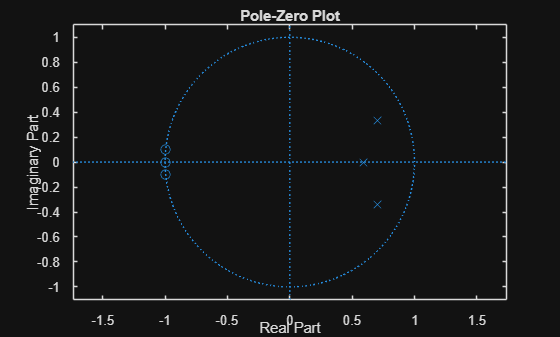

zplane(b, a);

Det kan ses, at polerne er indenfor enhedscirkelen, dvs. at filteret er stablit.

4-4

clear; clc;
F_s = 5e3; A_1 = 5; A_2 = 3; F_1 = 50; F_2 = 1e3;

Der ville ikke opstå aliasering af signalet, fordi nyquist frekvensen er 2500Hz.

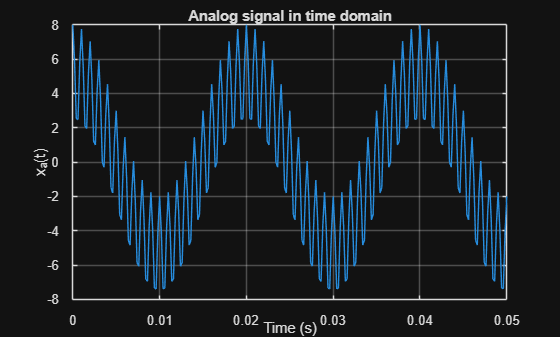

t = time_vec(F_s, 1024);

x_a = A_1*cos(2*pi*F_1*t) + A_2*cos(2*pi*F_2*t);

figure;
plot(t, x_a);
xlabel('Time (s)');
xlim([0 0.05]);
ylabel('x_a(t)');
title('Analog signal in time domain');
grid on;

4-5

Filter fra 4-1

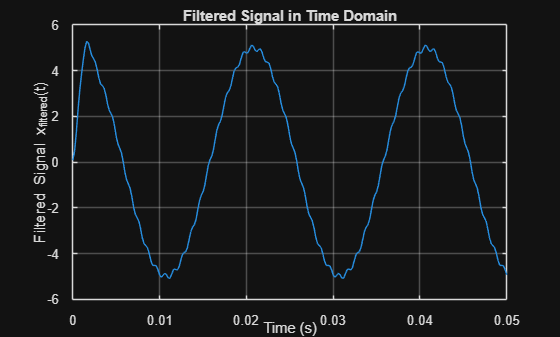

bd = [0.0102 0.0305 0.0305 0.0102]; ad = [1 -2.0038 1.4471 -0.3618];

% Apply the digital filter to the analog signal
x_filtered = filter(bd, ad, x_a);

% Plot the filtered signal in the time domain
figure;
plot(t, x_filtered);
xlim([0 0.05]);
xlabel('Time (s)');
ylabel('Filtered Signal x_{filtered}(t)');
title('Filtered Signal in Time Domain');
grid on;